# Detect Speech in a wav file

Adapted by G.Fraga Gonzalez from example file (~*MATLAB\R2021a\examples\audio\main\DetectPresenceOfSpeechExample*)*. *Documentation: [*https://ch.mathworks.com/help/audio/ref/detectspeech.html*](https://ch.mathworks.com/help/audio/ref/detectspeech.html) 

## Select Audio File

Find wav files in current folder 

dirinput = 'V:\gfraga\SPINCO\Sound_files\LIRI_voice_SM\words_v1';
diroutput = 'V:\gfraga\SPINCO\Sound_files\LIRI_voice_SM\words_v1_detect'; % should not end with \
files = dir([dirinput,'\*.wav']);
files= string({files.name});
fileinput = files(16);
cd(dirinput)

Read audio signal

[audioIn,fs] = audioread(fileinput);
% select only one column if multiple
if width(audioIn)>1
    audioIn = audioIn(:,1);
end
maxDataPoint = length(audioIn); % used later on for concision

## Call Function *d*`etectSpeech`

%% If you specify no output arguments to display a plot of the detected speech regions.e.g.: 
    %detectSpeech(audioIn,fs)

The `detectSpeech` function uses a thresholding algorithm based on energy and spectral spread per analysis frame. You can modify the `Window`, `OverlapLength`, and `MergeDistance` to fine-tune the algorithm for your specific needs.

use_default_window=false;
if use_default_window == 1
    win = hann(round(0.03*fs),'periodic'); 
    disp (['Using default window for speechDetect'])
    winInf = 'default'
else  
    disp(['Using window duration specified by slider', ' (windowDuration: ',num2str(windowDuration),')'])
    winInf = num2str(windowDuration);
    windowDuration = 0.068; % seconds
    numWindowSamples = round(windowDuration*fs);
    win = hamming(numWindowSamples,'periodic');  
end 

Using window duration specified by slider (windowDuration: 0.096)



idx = detectSpeech(audioIn,fs,"Window",win);

Expand selection boundaries at start and end

add_head_ms = 100; % additional ms at the start of selection
add_tail_ms = 100; % additional ms at the end of selection


Figure

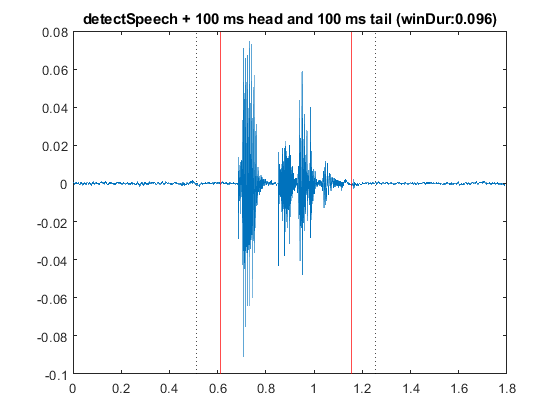

plot((1:maxDataPoint)/fs, audioIn)
title(['detectSpeech + ', num2str(add_head_ms),' ms head and ',num2str(add_tail_ms),' ms tail (winDur:',winInf,')'])
xline([idx(1)/fs, idx(2)/fs],'color','red')
xline([(idx(1)/fs)-(add_head_ms*0.001*fs)/fs, (idx(2)/fs)+(add_tail_ms*0.001*fs)/fs],'color','black','LineStyle',':');

fig1=gcf;
%%  The following commented lines are more relevant if separating speech in sentences:
% percentOverlap = 62;
% overlap = round(numWindowSamples*percentOverlap/100);
%
% mergeDuration = 0.34;
% mergeDist = round(mergeDuration*fs);
%
% detectSpeech(audioIn,fs,"Window",win,"OverlapLength",overlap,"MergeDistance",mergeDist)

#### play selection  

*(Warning: rudimentary volume control. Check your system volume first )*

 
intensity =1.86;
player = audioplayer(audioIn(idx(1):idx(2))*intensity,fs);
play(player) ;

## Manually Detect Speech

Define some segments manually 

manual_start = 56434;
manual_end = 85920;

Expand selection boundaries at start and end

add_head_ms = 100; % additional ms at the start of selection
add_tail_ms = 100; % additional ms at the end of selection


Figure

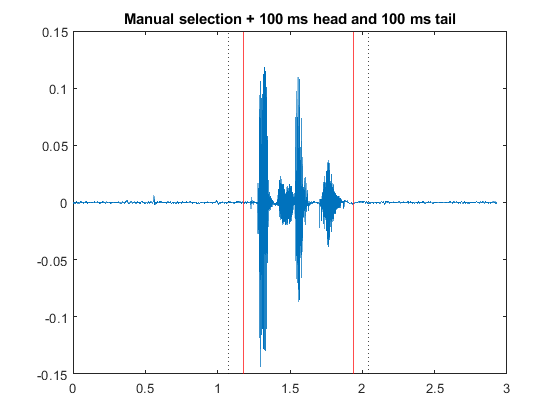

close gcf
plot((1:maxDataPoint)/fs, audioIn)
title(['Manual selection + ', num2str(add_head_ms),' ms head and ',num2str(add_tail_ms),' ms tail'])
xline([manual_start/fs, manual_end/fs],'color','red')
xline([(manual_start/fs)-(add_head_ms*0.001*fs)/fs, (manual_end/fs)+(add_tail_ms*0.001*fs)/fs],'color','black','LineStyle',':');

fig2=gcf;

#### play selection  

*(Warning: rudimentary volume control. Check your system volume first )*

 
intensity =3.1;
player = audioplayer(audioIn(manual_start:manual_end)*intensity,fs);
play(player);

## Save selected

Select what to save

stuff2save = "manual"

stuff2save = "manual"

Save stuff

saved manual


 
if exist ('fig1','var') && exist('fig2','var')
    % segment based on function 
    startpoint = idx(1)-(add_head_ms*0.001*fs);
    endpoint = idx(2)+(add_tail_ms*0.001*fs)  ;
    signal2save_detect = audioIn(startpoint:endpoint);
    outputname_detect = strrep(fileinput,'.wav','_detected.wav');
    
    % segment based on manual
    startpoint = manual_start-(add_head_ms*0.001*fs);
    endpoint = manual_end+(add_tail_ms*0.001*fs)  ;
    signal2save_manual = audioIn(startpoint:endpoint);
    outputname_manual = strrep(fileinput,'.wav','_manualSeg.wav');
    
    
    if contains(stuff2save,'detectSpeech')
        audiowrite(strcat(diroutput,'\',outputname_detect),signal2save_detect,fs);
        print(fig1, '-djpeg', strrep(outputname_detect,'.wav','.jpg'));    
        disp(strcat("saved ",stuff2save))
    
    elseif contains(stuff2save,'manual')
        audiowrite(strcat(diroutput,'\',outputname_manual),signal2save_detect,fs);
        print(fig2, '-djpeg', strrep(outputname_manual,'.wav','.jpg'));     
        disp(strcat("saved ",stuff2save))
    
    elseif contains(stuff2save,'both')
        audiowrite(strcat(diroutput,'\',outputname_detect),signal2save_detect,fs);
        print(fig1, '-djpeg', strrep(outputname_detect,'.wav','.jpg'));
     
        audiowrite(strcat(diroutput,'\',outputname_manual),signal2save_manual,fs);
        print(fig2, '-djpeg', strrep(outputname_manual,'.wav','.jpg'));
    
         disp(strcat("saved ",stuff2save))
    end
else
    disp('please generate both plots before trying to save any')
end 

 cd (diroutput)